Parameters

m_cart = 1; 
m_pen1 = 0.5;          % mass tank 1
m_pen2 = 0.5;          % mass tank 2
M_tank2 = 1.2;         % Total tank 2 mass
damp_coef = 0.005;       % damping pendulum 1
dpx = 0.05;            % damping pendulum 2
inert_pen = 0.06;      % pendulum 1 inertia
g = 9.8;
l1 = 0.3;              % pendulum 1 length
l2 = 0.5;              % pendulum 2 length

u_max = 0.5;

p = inert_pen*(m_cart+m_pen1) + m_cart*m_pen1*l1^2;

initial condition

theta10 = 25;
theta20 = 0;

Continuous-time matrices

A = [0 1 0 0;
     0 -(inert_pen + m_pen1*l1^2)*damp_coef/p  -m_pen1^2*g*l1^2/p  0;
     0 0 0 1;
     0 -m_pen1*l1*damp_coef/p          -m_pen1*g*l1*(m_cart + m_pen1)/p  0];

B1 = [0;
      (inert_pen + m_pen1*l1^2)/p;
      0;
      m_pen1*l1/p];  % control input

B2 = [0;
      1/p;
      0;
      l1*(m_cart + m_pen1)/p];  % disturbance torque

B = [B1 B2];

C = [1 0 0 0;
     0 0 1 0];
D = zeros(2,2);

states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u', 'd'};
outputs = {'x'; 'phi'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

Discretize

Ts = 1/100;
sys_d = c2d(sys_ss, Ts, 'zoh');

A = sys_d.a;
B = sys_d.b;
C = sys_d.c;
D = sys_d.d;

% === LQR Controller ===
Q = C'*C;
R = 0.01;
K = dlqr(A,B(:,1),Q,R);

Ac = A - B(:,1)*K;
Bc = B(:,2);  % disturbance
Cc = C;
Dc = D(:,2);

sys_cl = ss(Ac,Bc,Cc,Dc,Ts,'statename',states,'inputname',{'d'},'outputname',outputs);

Initial state

x0 = [0; 0; deg2rad(theta10); 0];
t = 0:Ts:15;

disturbance

impulse_time = 5;
impulse_index = round(impulse_time / Ts);
d = zeros(length(t), 1);
impulse_strength = 0.5 * 0.2; % 0.2*(rand() - 0.5);
d(impulse_index) = impulse_strength / Ts;

Run

% [y, t, x] = lsim(sys_cl, d, t, x0);
sys_full = ss(Ac, Bc, eye(4), zeros(4,1), Ts);
[x_states, t_out, ~] = lsim(sys_full, d, t, x0);

second pendulum

% === Control input u(t) ===
theta2 = zeros(size(t));
theta2_dot = zeros(size(t));
theta2(1) = deg2rad(theta20);

% Cart acceleration from system
x_ddot = zeros(length(t), 1);
u = zeros(length(t), 1);

% === Manual feedback gains for sloshing (pendulum 2) ===
k2 = 5;
k2_dot = 0.5;

theta2_with = zeros(length(t)+1,1);
theta2_dot_with = zeros(length(t)+1,1);
theta2_without = zeros(length(t)+1,1);
theta2_dot_without = zeros(length(t)+1,1);

theta2_with(1) = deg2rad(theta20);
theta2_without(1) = deg2rad(theta20);

u_with = zeros(length(t),1);
u_without = zeros(length(t),1);

for i = 1:length(t)
    xi = x_states(i,:)';
    
    % Control input
    u_with(i) = -K * xi - k2 * theta2_with(i) - k2_dot * theta2_dot_with(i);
    u_with(i) = min(max(u_with(i), -u_max), u_max);

    u_without(i) = -K * xi;

    % Cart acceleration (based on closed-loop system)
    x_ddot(i) = A(2,:) * xi + B(2,1) * u_with(i);  % same A,B for both

    % === Sloshing Dynamics WITH control ===
    th = theta2_with(i);
    th_dot = theta2_dot_with(i);
    th_ddot = -(g/l2)*sin(th) - (x_ddot(i)/l2)*cos(th) - (dpx/(m_pen2*l2^2)) * th_dot;
    theta2_dot_with(i+1) = th_dot + Ts * th_ddot;
    theta2_with(i+1) = th + Ts * theta2_dot_with(i+1);

    % === Sloshing Dynamics WITHOUT control ===
    th = theta2_without(i);
    th_dot = theta2_dot_without(i);
    th_ddot = -(g/l2)*sin(th) - (x_ddot(i)/l2)*cos(th) - (dpx/(m_pen2*l2^2)) * th_dot;
    theta2_dot_without(i+1) = th_dot + Ts * th_ddot;
    theta2_without(i+1) = th + Ts * theta2_dot_without(i+1);
end

theta2_deg_with = rad2deg(theta2_with(1:end-1));
theta2_deg_without = rad2deg(theta2_without(1:end-1));
angle_deg = rad2deg(x_states(:,2));

% === Second Animation: Pendulums with Stationary Cart ===
phi_no_cart = zeros(length(t)+1,1);
phi_dot_no_cart = zeros(length(t)+1,1);
theta2_no_cart = zeros(length(t)+1,1);
theta2_dot_no_cart = zeros(length(t)+1,1);

% Initial conditions
phi_no_cart(1) = deg2rad(theta10); 
theta2_no_cart(1) = deg2rad(theta20);

% Simulate dynamics of both pendulums without cart motion
for i = 1:length(t)
    % === Pendulum 1 dynamics (with impulse torque) ===
    torque_impulse = d(i);  % applied only once at t = 5s
    phi = phi_no_cart(i);
    phi_dot = phi_dot_no_cart(i);
    
    % Equation: I*phi_ddot + damping*phi_dot + m*g*l*sin(phi) = torque
    phi_ddot = (torque_impulse - damp_coef * phi_dot - m_pen1 * g * l1 * sin(phi)) / inert_pen;
    
    phi_dot_no_cart(i+1) = phi_dot + Ts * phi_ddot;
    phi_no_cart(i+1) = phi + Ts * phi_dot_no_cart(i+1);
    
    % === Pendulum 2 dynamics (sloshing, no cart acceleration) ===
    th = theta2_no_cart(i);
    th_dot = theta2_dot_no_cart(i);
    
    th_ddot = -(g/l2)*sin(th) - (dpx/(m_pen2*l2^2)) * th_dot;  % no x_ddot
    theta2_dot_no_cart(i+1) = th_dot + Ts * th_ddot;
    theta2_no_cart(i+1) = th + Ts * theta2_dot_no_cart(i+1);
end

#### Plot input

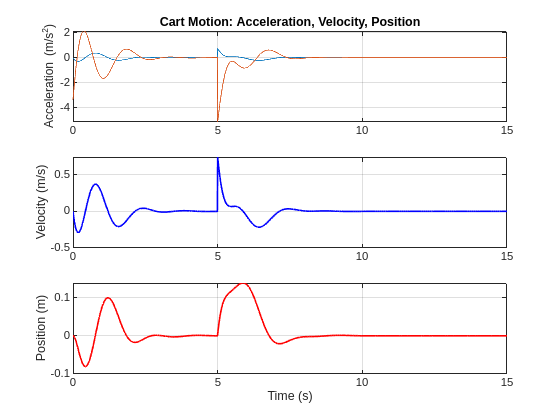

x_pos = x_states(:,1);        % cart position
x_vel = x_states(:,2);        % cart velocity
x_acc = x_ddot;        % cart acceleration already computed
figure;
subplot(3,1,1);
plot(t, x_acc, t, u_without);
ylabel('Acceleration (m/s^2)');
title('Cart Motion: Acceleration, Velocity, Position');
grid on;

subplot(3,1,2);
plot(t, x_vel, 'b', 'LineWidth', 1.2);
ylabel('Velocity (m/s)');
grid on;

subplot(3,1,3);
plot(t, x_pos, 'r', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Position (m)');
grid on;

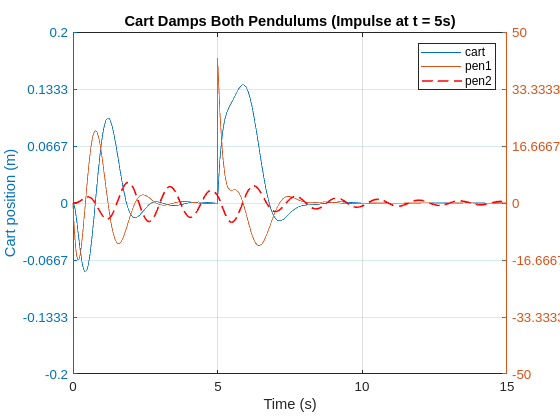

figure;
[AX, ~, ~] = plotyy(t, x_states(:,1), t, angle_deg, 'plot');
hold(AX(2), 'on');
plot(AX(2), t, theta2_deg_with, 'r--', 'LineWidth', 1.2);

cart_limit = ceil(max(abs(x_states(:,1)))*1.1*10)/10;
angle_limit = ceil(max(abs(angle_deg))*1.1/10)*10;

set(AX(1), 'YLim', [-cart_limit cart_limit]);
set(AX(2), 'YLim', [-angle_limit angle_limit]);
set(AX(1), 'YTick', linspace(-cart_limit, cart_limit, 7));
set(AX(2), 'YTick', linspace(-angle_limit, angle_limit, 7));

set(get(AX(1),'Ylabel'), 'String', 'Cart position (m)')
set(get(AX(2),'Ylabel'), 'String', 'Pendulum angle (deg)')
xlabel('Time (s)')
title('Cart Damps Both Pendulums (Impulse at t = 5s)')
legend(["cart", "pen1", "pen2"])
grid on

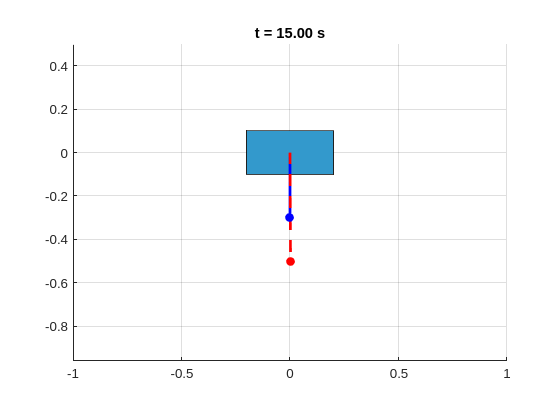


% === Plot 2: Control Input Comparison ===
figure;
plot(t, u_with, 'b', 'LineWidth', 1.2); hold on;
plot(t, u_without, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)')
ylabel('Control Input u(t)')
title('Control Effort Comparison')
grid on

legend(["With sloshing damping", "Without sloshing damping"], "Position", [0.5284 0.1362 0.3750, 0.1073])


disp(['Impulse torque applied at t = 5s with strength: ', num2str(impulse_strength, '%.4f'), ' N·m·s'])

Impulse torque applied at t = 5s with strength: 0.1000 N·m·s


animation

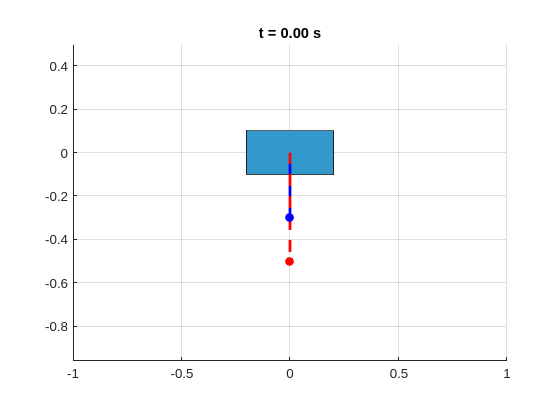

% Visualization parameters
cart_width = 0.4;
cart_height = 0.2;
pend_length1 = l1;
pend_length2 = l2;
cart_y = 0;

figure(4);
for i = 1:5:length(t)  % reduce frame rate for speed
    clf;
    hold on;
    axis equal;
    grid on;
    xlim([-1 1]);
    ylim([-1.2*(l1 + l2), 0.5]);

    % Cart position
    cart_x = x_states(i,1);
    
    % First pendulum angle
    phi = x_states(i,2);
    
    % Second pendulum angle
    theta = theta2_with(i);
    
    % Cart
    rectangle('Position', [cart_x - cart_width/2, cart_y - cart_height/2, cart_width, cart_height], ...
              'FaceColor', [0.2 0.6 0.8]);

    % First pendulum endpoint
    pend1_x = cart_x + pend_length1 * sin(phi);
    pend1_y = cart_y - pend_length1 * cos(phi);
    
    % Second pendulum endpoint (attached to cart, not first pendulum)
    pend2_x = cart_x + pend_length2 * sin(theta);
    pend2_y = cart_y - pend_length2 * cos(theta);

    % Draw pendulums
    plot([cart_x pend1_x], [cart_y pend1_y], 'b-', 'LineWidth', 2);  % first pendulum
    plot([cart_x pend2_x], [cart_y pend2_y], 'r--', 'LineWidth', 2);  % second pendulum

    % Draw masses at the end
    plot(pend1_x, pend1_y, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
    plot(pend2_x, pend2_y, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');

    title(sprintf('t = %.2f s', t(i)));
    drawnow;
end


% figure;
% for i = 1:5:length(t)
%     clf;
%     hold on;
%     axis equal;
%     grid on;
%     xlim([-1 1]);
%     ylim([-1.2*(l1 + l2), 0.5]);
% 
%     cart_x = 0;  % stationary cart
%     cart_y = 0;
% 
%     % Current angles
%     phi = phi_no_cart(i);
%     theta = theta2_no_cart(i);
% 
%     % Cart
%     rectangle('Position', [cart_x - cart_width/2, cart_y - cart_height/2, cart_width, cart_height], ...
%               'FaceColor', [0.5 0.5 0.5]);
% 
%     % Pendulum 1 endpoint
%     pend1_x = cart_x + pend_length1 * sin(phi);
%     pend1_y = cart_y - pend_length1 * cos(phi);
% 
%     % Pendulum 2 endpoint
%     pend2_x = cart_x + pend_length2 * sin(theta);
%     pend2_y = cart_y - pend_length2 * cos(theta);
% 
%     % Draw pendulums
%     plot([cart_x pend1_x], [cart_y pend1_y], 'b-', 'LineWidth', 2);
%     plot([cart_x pend2_x], [cart_y pend2_y], 'r--', 'LineWidth', 2);
% 
%     % Mass markers
%     plot(pend1_x, pend1_y, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b');
%     plot(pend2_x, pend2_y, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
% 
%     title(sprintf('Stationary Cart | t = %.2f s', t(i)));
%     drawnow;
% end